clc; clear; close all
rng("default")

load("C2_patches.mat")
% 2D
C = 27;
d = 4;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

n_lst = 20 * 2.^(0:4)

n_lst =     20    40    80   160   320


h_lst = 0.01 * (1/2).^(0:4);

C2_patches = cell(length(n_lst), 1);
C2_norms = cell(length(h_lst), 1);

% Construct FC Patches
for i=1:length(n_lst)
    n_C2 = n_lst(i);
    h_S = h_lst(i);
    n_S = n_C2; % 10;%ceil(21/20*n_C2);
    
    C2_patch = construct_C2_patch(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
    C2_patch = C2_patch.FC(C, d, A, Q, nan);
    
    [C2_bound_X, C2_bound_Y] = C2_patch.boundary_mesh_xy();
    R = R_cartesian_mesh_obj(C2_patch.x_min, C2_patch.x_max, C2_patch.y_min, C2_patch.y_max, h_S, C2_bound_X, C2_bound_Y);
    
    R.interpolate_patch(C2_patch, 5, true);
    max(R.f_R(R.interior_idxs) - f(R.R_X(R.interior_idxs), R.R_Y(R.interior_idxs)))
    
    
    R.compute_fc_coeffs();
    [R_X_err, R_Y_err, f_interpolation, interior_idx] = R.ifft_interpolation(R.h./2);
        
    max(abs(f(R_X_err(interior_idx), R_Y_err(interior_idx))-f_interpolation(interior_idx)))

end

start first pass
construct nan map


ans = 1.7913e-05

ans = 2.8409e-05

start first pass
construct nan map


ans = 6.4692e-07

ans = 1.1735e-06

start first pass
construct nan map


ans = 1.6745e-08

ans = 2.7705e-08

start first pass
construct nan map


ans = 6.3354e-10

ans = 6.8238e-09

start first pass
construct nan map


ans = 3.9909e-11

ans = 2.9011e-08

clc; clear;
rng("default")

% 2D
C = 27;
d = 4;

load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

n_lst = 20 * 2.^(1:3)

n_lst =     40    80   160


h_lst = 0.01 * (1/2).^(1:3);

% Construct FC Patches
for i=2%:length(n_lst)
    n_C2 = n_lst(i);
    h_S = h_lst(i);
    n_S = n_C2; % 10;%ceil(21/20*n_C2);
    
    C2_patch = construct_C2_patch(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
    C2_patch = C2_patch.FC(C, d, A, Q, nan);
    
    [C2_bound_X, C2_bound_Y] = C2_patch.boundary_mesh_xy();
    R = R_cartesian_mesh_obj(C2_patch.x_min, C2_patch.x_max, C2_patch.y_min, C2_patch.y_max, h_S, C2_bound_X, C2_bound_Y);
    
    R.interpolate_patch(C2_patch, 5, true);
    max(R.f_R(R.interior_idxs) - f(R.R_X(R.interior_idxs), R.R_Y(R.interior_idxs)))
    
    
    R.compute_fc_coeffs();
    [R_X_err, R_Y_err, f_interpolation, interior_idx] = R.ifft_interpolation(R.h./2);
        
    max(abs(f(R_X_err(interior_idx), R_Y_err(interior_idx))-f_interpolation(interior_idx)))
    
    y_err_mesh = transpose(R.y_start:R.h/2:R.y_end+R.h/2);
    N = length(y_err_mesh);

    errs = zeros(size(R.f_R, 2), 1);
    for j = 1:size(R.f_R, 2)
        x_err_mesh = R.R_X(1, j)*ones(N, 1);
        fc_coeffs = fftshift(1/R.n_y * fft(R.f_R(:, j)));
    
        padded_fc_coeffs = [zeros(floor((N-R.n_y)/2), 1); fc_coeffs; zeros(ceil((N-R.n_y)/2), 1)];
        f_numeric = N*real(ifft(ifftshift(padded_fc_coeffs)));
        
        in_interior = inpolygon(x_err_mesh, y_err_mesh, R.boundary_X, R.boundary_Y);
        
        if sum(in_interior) > 0
            errs(j) = max(abs(f_numeric(in_interior) - f(x_err_mesh(in_interior), y_err_mesh(in_interior))));
        end
    end

end

start first pass
construct nan map


ans = 1.6745e-08

ans = 2.7705e-08

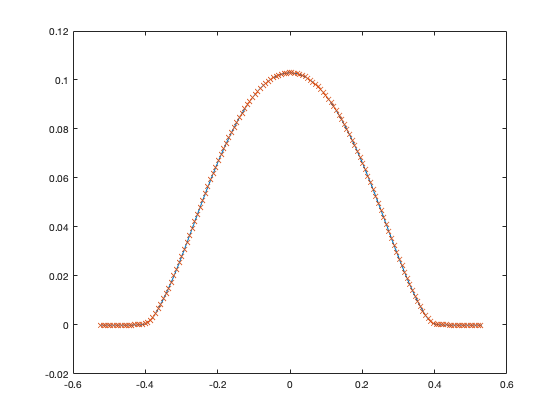

ans = 142

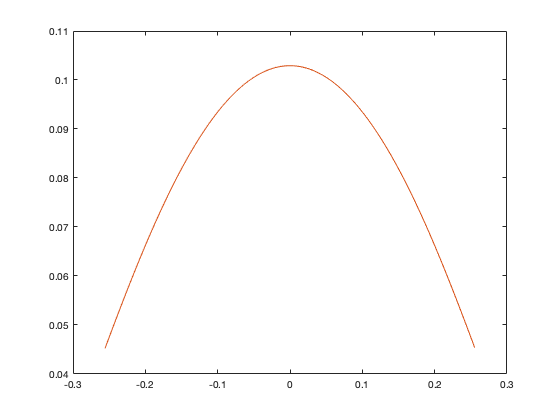

ans = 	1.0e+-8 *

    0.4116
   -0.0066
    0.1322
    0.3530
   -0.1450
   -0.5106
   -0.0047
    0.4274
   -0.0008
   -0.4012


for j = 74%1:size(R.f_R, 2)
    x_err_mesh = R.R_X(1, j)*ones(N, 1);
    fc_coeffs = fftshift(1/R.n_y * fft(R.f_R(:, j)));

    padded_fc_coeffs = [zeros(floor((N-R.n_y)/2), 1); fc_coeffs; zeros(ceil((N-R.n_y)/2), 1)];
    f_numeric = N*real(ifft(ifftshift(padded_fc_coeffs)));
    
    in_interior = inpolygon(x_err_mesh, y_err_mesh, R.boundary_X, R.boundary_Y);
    
    figure;
    plot(y_err_mesh, f_numeric)
    hold on;
    plot(R.R_Y(:, j), R.f_R(:, j), 'x')
    sum(in_interior)
    
    figure;
    plot(y_err_mesh(in_interior), f(x_err_mesh(in_interior), y_err_mesh(in_interior)))
    hold on;
    plot(y_err_mesh(in_interior), f_numeric(in_interior))
    
    f_numeric(in_interior) - f(x_err_mesh(in_interior), y_err_mesh(in_interior))
end

clc; clear; close all
rng("default")

load("C2_patches.mat")
% 2D
C = 54;
d = 8;

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C), '.mat']);
A = double(A);
Q = double(Q);

l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

n_lst = 20 * 2.^(0:4)

n_lst =     20    40    80   160   320


h_lst = 0.029 * (1/2).^(0:4);

errs = zeros(length(n_lst), 1);
% Construct FC Patches
for i=1:length(n_lst)
    n_C2 = n_lst(i);
    h_S = h_lst(i);
    n_S = n_C2; % 10;%ceil(21/20*n_C2);
    
    C2_patch = construct_C2_patch(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
%     [XI, ETA] = C2_patch.xi_eta_mesh();
%     C2_patch.f_XY = f_smooth(XI, ETA);
    
    C2_fcont_patch = C2_patch.FC(C, d, A, Q, nan);
    
    [C2_bound_X, C2_bound_Y] = C2_patch.boundary_mesh_xy();
    R = R_cartesian_mesh_obj(C2_fcont_patch.x_min, C2_fcont_patch.x_max, C2_fcont_patch.y_min, C2_fcont_patch.y_max, h_S, C2_bound_X, C2_bound_Y);
    R_err = R_cartesian_mesh_obj(C2_fcont_patch.x_min, C2_fcont_patch.x_max, C2_fcont_patch.y_min, C2_fcont_patch.y_max, h_S./2, C2_bound_X, C2_bound_Y);
    
    [P, R_patch_idxs] = R.interpolate_patch(C2_fcont_patch, d+3, true);
%     [P_err, R_patch_idxs_err] = R_err.interpolate_patch(C2_patch, 5, true);
    
%     f_exact = zeros(R_err.n_y, R_err.n_x);
%     for j = 1:length(R_patch_idxs_err)
%         xi_eta_point = P_err(R_patch_idxs_err(j));
%         f_exact(R_patch_idxs_err(j)) = f_smooth((xi_eta_point(1)-p0)/Rp, (xi_eta_point(2)-p0)/Rp);
%     end
    
    R.compute_fc_coeffs();

    [R_X_err, R_Y_err, f_interpolation, interior_idx] = R.ifft_interpolation(R.h./2);

    errs(i) = max(abs(f(R_X_err(interior_idx), R_Y_err(interior_idx))-f_interpolation(interior_idx)));    
end

start first pass
construct nan map
start first pass
construct nan map
start first pass
construct nan map
start first pass
construct nan map
start first pass
construct nan map



errs

errs =      1.567210798264379e-02
     2.955543078372869e-05
     7.732270754234882e-09
     2.503392299013640e-09
     2.339981042265293e-09


clc; clear; close all
rng("default")

load("C2_patches.mat")
% 2D
C = 54;
d = 8;

load(['FC_data/A_d',num2str(d),'_C', num2str(C), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(C), '.mat']);
A = double(A);
Q = double(Q);

l_theta = @(theta) [2*sin(theta/2), -sin(theta)];

n_lst = 20 * 2.^(0:4)
h_lst = 0.029 * (1/2).^(0:4);

errs = zeros(length(n_lst), 1);
% Construct FC Patches
for i=1:length(n_lst)
    n_C2 = n_lst(i);
    h_S = h_lst(i);
    n_S = n_C2; % 10;%ceil(21/20*n_C2);
    
    C2_patch = construct_C2_patch(@(x, y) f(x, y), 0.4, 2*pi-0.4, 0, n_C2, n_C2);
    
    C2_fcont_patch = C2_patch.FC(C, d, A, Q, nan);
    
    [C2_bound_X, C2_bound_Y] = C2_patch.boundary_mesh_xy();
    R = R_cartesian_mesh_obj(C2_fcont_patch.x_min, C2_fcont_patch.x_max, C2_fcont_patch.y_min, C2_fcont_patch.y_max, h_S, C2_bound_X, C2_bound_Y);
    R_err = R_cartesian_mesh_obj(C2_fcont_patch.x_min, C2_fcont_patch.x_max, C2_fcont_patch.y_min, C2_fcont_patch.y_max, h_S./2, C2_bound_X, C2_bound_Y);
    
    [P, R_patch_idxs] = R.interpolate_patch(C2_fcont_patch, d+3, true);
%     [P_err, R_patch_idxs_err] = R_err.interpolate_patch(C2_patch, 5, true);
    
%     f_exact = zeros(R_err.n_y, R_err.n_x);
%     for j = 1:length(R_patch_idxs_err)
%         xi_eta_point = P_err(R_patch_idxs_err(j));
%         f_exact(R_patch_idxs_err(j)) = f_smooth((xi_eta_point(1)-p0)/Rp, (xi_eta_point(2)-p0)/Rp);
%     end
    
    R.compute_fc_coeffs();

    [R_X_err, R_Y_err, f_interpolation, interior_idx] = R.ifft_interpolation(R.h./2);

    errs(i) = max(abs(f(R_X_err(interior_idx), R_Y_err(interior_idx))-f_interpolation(interior_idx)));    
end

errs

function C2_patch = construct_C2_patch(f, theta_A, theta_B, theta_C, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) xi*(theta_A - theta_C) + theta_C;
    l_B = @(eta) eta*(theta_B - theta_C - 2*pi) + theta_C + 2*pi; % account for wrap around
    
    M_p = @(xi, eta) l_theta(l_A(xi)) + l_theta(l_B(eta)) - l_theta(theta_C);
    J = @(v) [theta_A*cos(v(1)*theta_A/2) (theta_B-2*pi)*cos((v(2)*(theta_B-2*pi)+2*pi)/2); -theta_A*cos(v(1)*theta_A) -(theta_B-2*pi)*cos(v(2)*(theta_B-2*pi)+2*pi)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p(XI(:), ETA(:));
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    C2_patch = C2_patch_obj(M_p, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, nan); % data associated with patch
end

function S_patch = construct_S_patch(f, theta_A, theta_B, h, n_xi, n_eta)
    l_theta = @(theta) [2*sin(theta/2), -sin(theta)];
    
    l_A = @(xi) (theta_B - theta_A)*xi + theta_A;
    nu = @(xi) [cos(l_A(xi)), cos(l_A(xi)/2)] ./ sqrt(cos(l_A(xi)).^2 + cos(l_A(xi)/2).^2);
    
    M_p_general = @(xi, eta, H) l_theta(l_A(xi)) + eta.*H.*nu(xi);
    % H is a function of h and n_eta
    
    theta_diff = theta_B - theta_A;
    J = @(v, H) [theta_diff*cos(l_A(v(1))/2)-v(2)*H*theta_diff*sin(l_A(v(1))), H*cos(l_A(v(1))); -1*theta_diff*cos(l_A(v(1)))-v(2)*H*theta_diff/2*sin(l_A(v(1))/2), H*cos(l_A(v(1))/2)];
    
    xi_mesh = linspace(0, 1, n_xi+1);
    eta_mesh = linspace(0, 1, n_eta+1);
    
    [XI, ETA] = meshgrid(xi_mesh, eta_mesh);
    XY = M_p_general(XI(:), ETA(:), h*n_eta);
    
    f_XY = reshape(f(XY(:, 1), XY(:, 2)), [n_eta+1, n_xi+1]);
    
    S_patch = S_patch_obj(M_p_general, J, n_xi, n_eta, 0, 1, 0, 1, f_XY, h, nan);
end

function f_y = f(x, y)
    r = sqrt(x.^2 + y.^2);
    f_y = zeros(size(x));
    f_y(r < 0.56) = exp(1./(1/0.56*r(r < 0.56).^2-0.56));
    f_y(r >= 0.56) = 0;
end

function f_y = f_smooth(x, y)
    f_y = zeros(size(x));
    interior_msk = x < 1 & x > 0 & y < 1 & y > 0;
    f_y(interior_msk) = exp(-1./(1-(2*x(interior_msk)-1).^2)).*exp(-1./(1-(2*y(interior_msk)-1).^2));
end